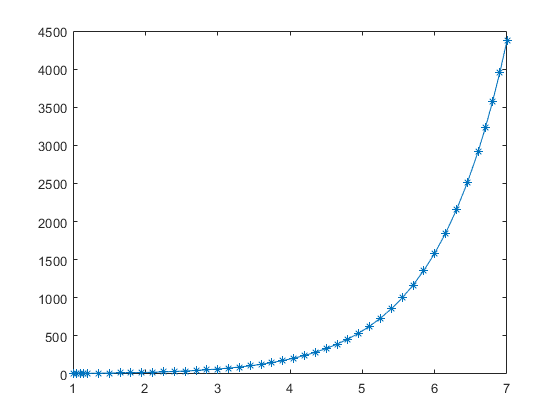

f = @(t, y) y + t^2-1;
y0 = 7;
[t, y] = ode45(f, [1 7], y0);

plot(t, y, '*-');

tspan = 0:0.2:1;
y0 = [1, 0];
f = @(t, y) [y(2); t^2*y(2) + 2*t*y(1) + 1];
[t, y] = ode45(f, tspan, y0);
for i = 1:length(tspan)
    fprintf('y(%f) = %f\n', t(i), y(i, 1));
end

y(0.000000) = 1.000000
y(0.200000) = 1.022702
y(0.400000) = 1.102595
y(0.600000) = 1.262645
y(0.800000) = 1.541062
y(1.000000) = 2.009335


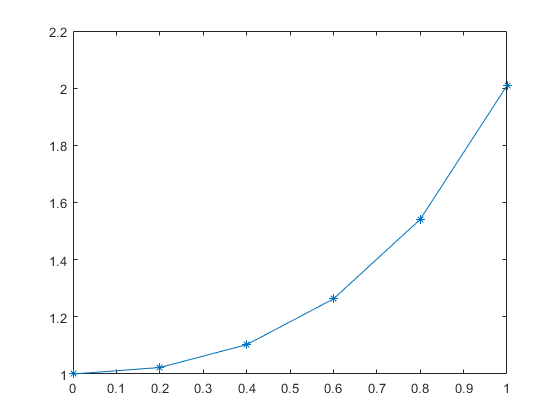

plot(t, y(:,1), '*-');

for i = 1:length(tspan)
    fprintf('y(%f) = %f\n', t(i), y(i, 2));
end

y(0.000000) = 0.000000
y(0.200000) = 0.240908
y(0.400000) = 0.576415
y(0.600000) = 1.054552
y(0.800000) = 1.786279
y(1.000000) = 3.009335


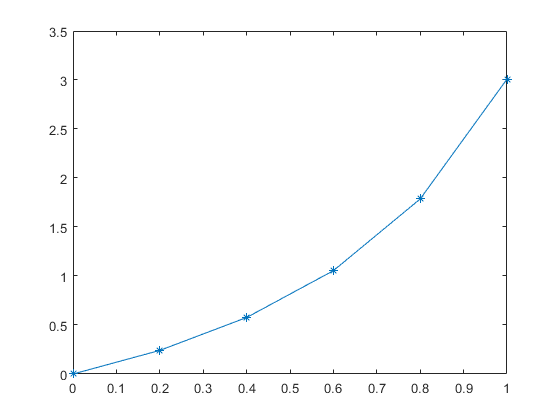

plot(t, y(:,2), '*-');